function isBracket = test_bracket(f,a,b,c)
    isBracket = f(b)<f(a) && f(b)<f(c);
end

function [n,a,b,c] = find_bracket(f)
    phi = 0.618;
    n = 0;
    a = (1 + phi)^(n);
    b = (1 + phi)^(n + 1);
    c = (1 + phi)^(n + 2);

    while ~test_bracket(f, a, b, c)
        fprintf("n=%d\n",n)
        fprintf("a0 = %d | f(a0) = %d\n",a,f(a));
        fprintf("b0 = %d | f(b0) = %d\n",b,f(b));
        fprintf("c0 = %d | f(c0) = %d\n\n",c,f(c));
        a = a * (1 + phi);
        b = b * (1 + phi);
        c = c * (1 + phi);
        n = n + 1;
    end
end

f = @(x) (cos(x)-1)/x^2

f = function_handle with value:
    @(x)(cos(x)-1)/x^2


[n,a,b,c]=find_bracket(f);

n=0
a0 = 1 | f(a0) = -4.596977e-01
b0 = 1.618000e+00 | f(b0) = -4.000063e-01
c0 = 2.617924e+00 | f(c0) = -2.722672e-01

n=1
a0 = 1.618000e+00 | f(a0) = -4.000063e-01
b0 = 2.617924e+00 | f(b0) = -2.722672e-01
c0 = 4.235801e+00 | f(c0) = -8.130360e-02

n=2
a0 = 2.617924e+00 | f(a0) = -2.722672e-01
b0 = 4.235801e+00 | f(b0) = -8.130360e-02
c0 = 6.853526e+00 | f(c0) = -3.369815e-03

n=3
a0 = 4.235801e+00 | f(a0) = -8.130360e-02
b0 = 6.853526e+00 | f(b0) = -3.369815e-03
c0 = 1.108901e+01 | f(c0) = -7.373621e-03



n

n = 4

%test_bracket(f,a,b,c)
f(a)

ans = -0.0034

f(b)

ans = -0.0074

f(c)

ans = -0.0012

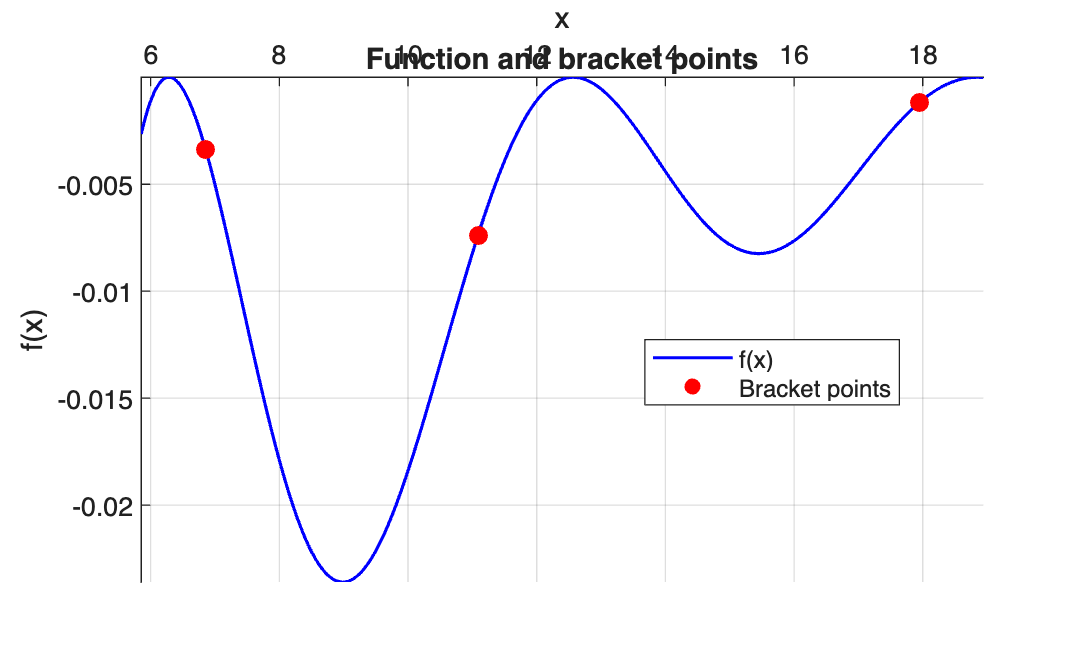


hold on;
density = 100;
xmax = max([a b c]) + 1;
xmin = min([a b c]) - 1;
range = xmax - xmin;
x = linspace(xmin, xmax, max(ceil(density * range), 100));
y = arrayfun(f, x);
plot(x, y, '-b', 'LineWidth', 1.2);

scatter([a b c], [f(a) f(b) f(c)], 50, 'r', 'filled');

ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
grid on;
xlabel('x');
ylabel('f(x)');
title('Function and bracket points');
legend('f(x)', 'Bracket points', 'Location', 'best');
axis tight;